# Attractor reconstruction for the Lorenz equations

Simulate the Lorenz equations, outputing the results with small uniform spacing in time.

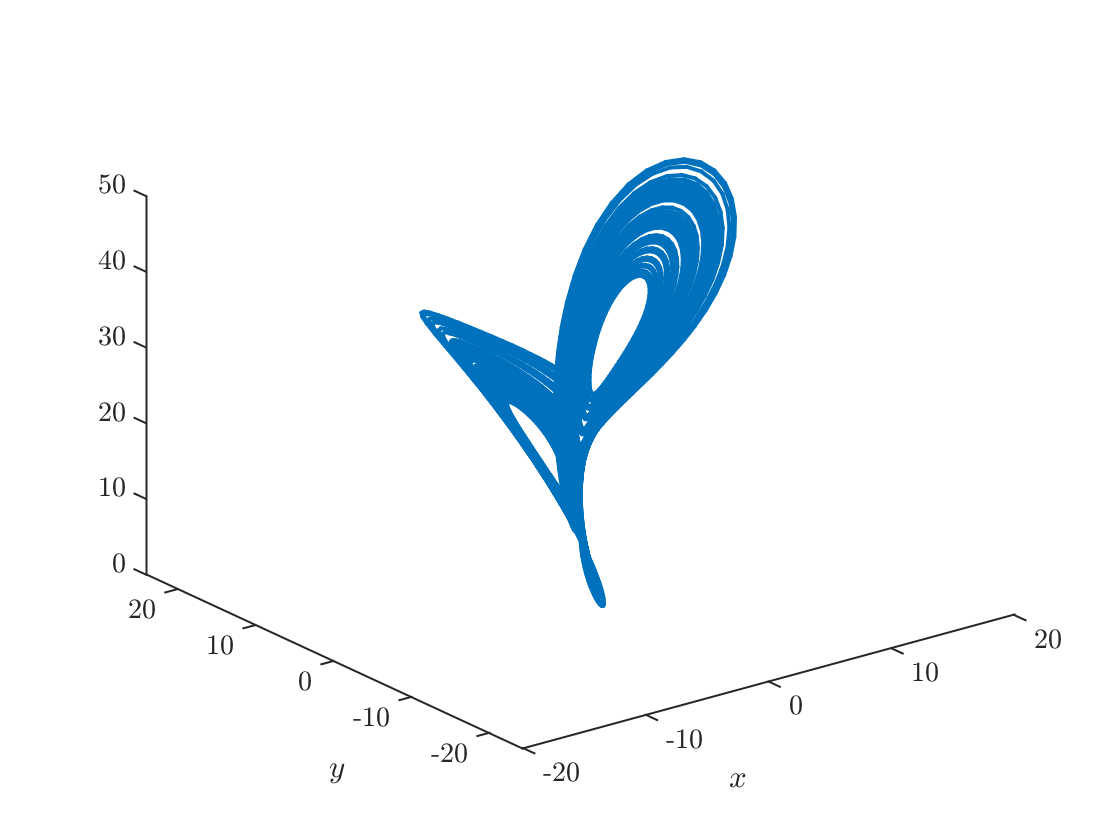

sigma=10; b=8/3; r=28;
f=@(t,y)lorenzODE(t,y,sigma,r,b);
fixedPoint=[sqrt(b*(r-1)),sqrt(b*(r-1)),r-1];
perturbation=[1 1 1];
y0=fixedPoint+perturbation;
tFinal=100;
tTransient=20;
dt=0.01;
tspan=0:dt:(tTransient+tFinal); %Note that by specifying tspan with more than two elements, this gives the output array t
[t,y]=ode45(f,tspan,y0);
p=find(t>=tTransient,1,'first');
t=t(p:end);y=y(p:end,:);
plot3(y(:,1),y(:,2),y(:,3))
xlabel('$x$'); ylabel('$y$');ylabel('$y$')

## Reconstruct using time-delay embedding

You can move the slider back and forth to change the lag in the time delay

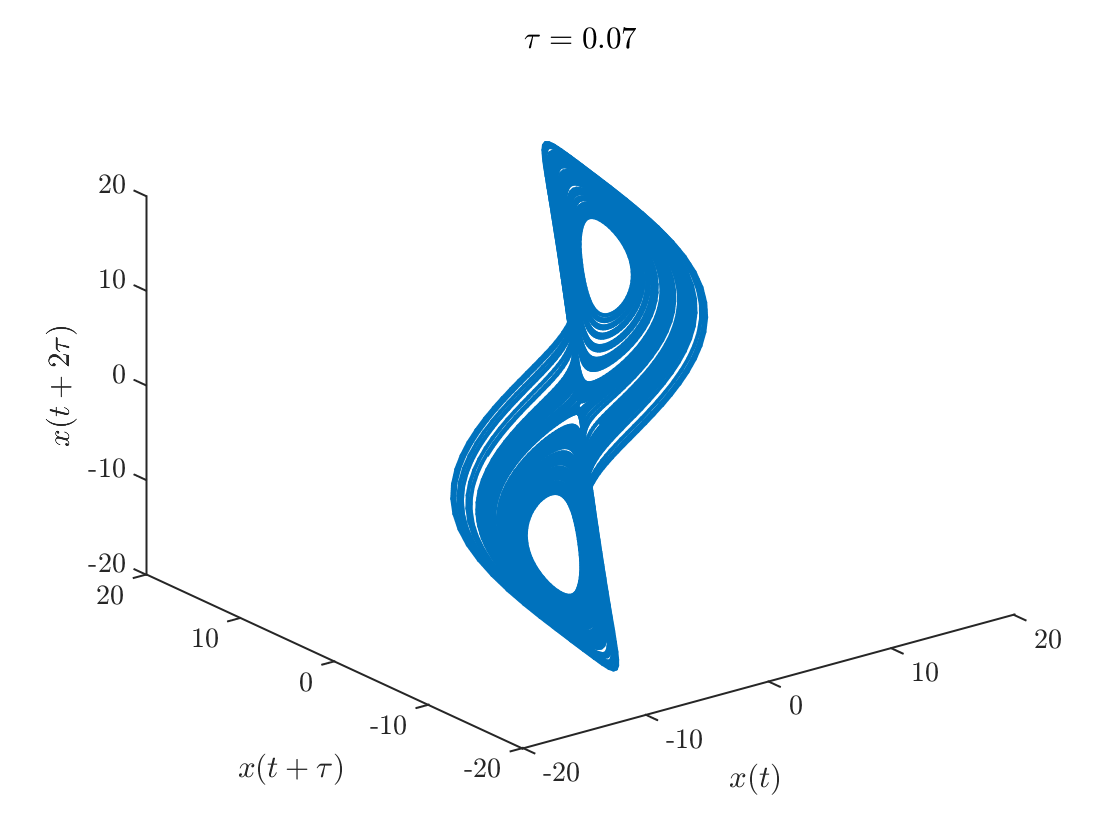

x=y(:,1);
dim=3;
lag=7;
ps=[];

for i=1:dim
    ps(:,i)=x(1+(i-1)*lag:end-(dim-(i-1))*lag);
end
plot3(ps(:,1),ps(:,2),ps(:,3))
xlabel('$x(t)$'); ylabel('$x(t+\tau)$');zlabel('$x(t+2\tau)$')
title(sprintf('$\\tau=%0.2f$',lag*dt))

## Function definitions

#### The ordinary differential equation

function dydt= lorenzODE(~,y,sigma,r,b)
dydt=zeros(3,1);
dydt(1) = sigma*(y(2)-y(1));
dydt(2) = r*y(1)-y(2) - y(1)*y(3);
dydt(3)= y(1)*y(2)-b*y(3);
end